Author: **Arjan Gupta**

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Final Exam Question 1

clear; close all; clc;

## Objective

Our objective is to find the equations of motion for the following 1-link manipulator.

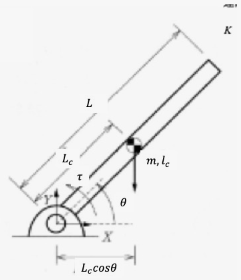

## Solution

**Lagrange-Euler (LE) method**

In this method, we take the following steps:

- Find the total kinetic energy of the system (*T)*

- Find the total potential energy of the system (U)

- Establish the Lagrangian as $L=T-U$

- Compute the derivatives for the Euler-Lagrange equation

- Show equation of motion

syms Lc theta(t) m1 I1 g tau

Step 1: Find total kinetic energy

For the total kinetic energy, we consider the linear kinetic energy, $\frac{1}{2}{\textrm{mv}}^2$ and the rotational energy, $\frac{1}{2}I\omega^2$. 

For the linear kinetic energy, we need the linear velocity, which is the magnitude of the resultant vector obtained by taking the time derivative of the position of $L_c$, which changes according to angle $\theta$.

For the rotational kinetic energy, we need the rotational velocity, which is simply need the time derivative of the angle $\theta$.

% Calculate linear velocity for link
x1 = Lc*cos(theta);
y1 = Lc*sin(theta);
lin_v1_squared = diff(x1,t)^2 + diff(y1,t)^2;
% Linear and rotational KE for link
KE_lin = (1/2)*m1*lin_v1_squared;
KE_rot = (1/2)*I1*(diff(theta,t))^2;
% Total KE for link
T = KE_lin + KE_rot;
display(T)

$$T(t) = \frac{I_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{1}\,\left({\mathrm{Lc}}^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\mathrm{Lc}}^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{2}$$

Step 2: Find total potential energy

The formula for total potential energy is simply $\textrm{PE}=m\cdot g\cdot h$. 

Accordingly to our figure, the center of mass of $m_1$ is at height $h\;=L_c \;\sin \left(\theta \right)$.

U = m1*g*Lc*sin(theta);
display(U)

$$U(t) = \mathrm{Lc}\,g\,m_{1}\,\sin\left(\theta \left(t\right)\right)$$

Step 3: Write the Lagrangian

The Lagrangian is $L=T-U$.

L = T - U;
display(L)

$$L(t) = \frac{I_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{1}\,\left({\mathrm{Lc}}^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\mathrm{Lc}}^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{2}-\mathrm{Lc}\,g\,m_{1}\,\sin\left(\theta \left(t\right)\right)$$

Step 4: Compute the derivatives for the Euler-Lagrange equation

The Euler-Lagrange equation as a dynamics equation is $\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial }{\partial \dot{q_k } }L\right)-\left(\frac{\partial }{\partial q_k }L\right)=\tau_k$, where *k *denotes the joint number. In this problem, we are considering only 1 joint, so there will be just 1 equation of motion.

% Assign q as the only joint variable, theta
q = theta;
% Compute derivatives
dL_q = diff(L,q);
dL_qdot = diff(L,diff(q,t));
dt = diff(dL_qdot,t);
% Shown the derivatives
display(dt)

$$dt(t) = \frac{m_{1}\,\left(2\,{\mathrm{Lc}}^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,{\mathrm{Lc}}^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)}{2}+I_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

display(dL_q)

$$dL\_q(t) = -\mathrm{Lc}\,g\,m_{1}\,\cos\left(\theta \left(t\right)\right)$$

Step 5: Show equation of motion

We now show our final answer for this problem.

% Set up the equation of motion
dyn_q_LHS = dt - dL_q;
dyn_q_LHS = simplify(dyn_q_LHS);
dyn_eq = dyn_q_LHS == tau;

% Show the equation of motion
display(dyn_eq)

$$dyn\_eq(t) = m_{1}\,{\mathrm{Lc}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+I_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+g\,m_{1}\,\cos\left(\theta \left(t\right)\right)\,\mathrm{Lc}=\tau$$